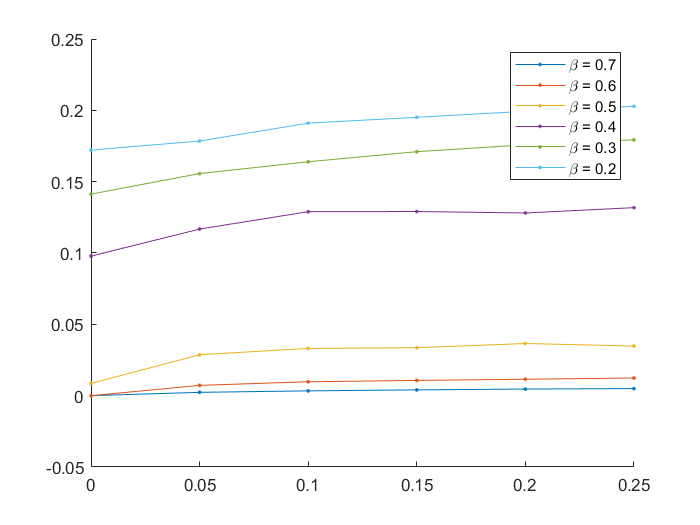


for i = [0.7,0.6,0.5]
    name = append('Action b = ',sprintf('%3.1f',i) ,'.txt');
    data = readtable(name);
    chem = data{[8:13],"Var1"};
    imagphisq =  data{[8:13],"Var6"};
    imagphi = data{[8:13],"Var5"};
    Iphi = power(imagphi,2);
    Y = imagphisq - Iphi;
    figure(1)
    hold on
    plot(chem,Y,'.-')
    hold off
end
for i = [0.4]
    name = append('Action b = ',sprintf('%3.1f',i) ,'.txt');
data = readtable(name);
chem = data{[8:13],"Var1"};
imagphisq =  data{[8:13],"Var6"}/(512*70000);
imagphi = data{[8:13],"Var5"}/(512*70000);
Iphi = power(imagphi,2);
Y = imagphisq - Iphi;
figure(1)
hold on
plot(chem,Y,'.-')
hold off
end
for i = [0.3,0.2]
    name = append('Action b = ',sprintf('%3.1f',i) ,'.txt');
    data = readtable(name);
    chem = data{[8:13],"Var1"};
    imagphisq =  data{[8:13],"Var6"};
    imagphi = data{[8:13],"Var5"};
    Iphi = power(imagphi,2);
    Y = imagphisq - Iphi;
    figure(1)
    hold on
    plot(chem,Y,'.-')
    hold off
end



legend({'\beta = 0.7','\beta = 0.6','\beta = 0.5','\beta = 0.4','\beta = 0.3','\beta = 0.2'})